# PCA for industrial diagnostics of compressor connection rod defects

Industrial production of compressors suffers from problems during the imprinting operation where a connection rod is connected with a compressor head. Irregular imprinting can cause damage or crack of the connection rod which results in a damaged compressor. Such compressors should be eliminated from the production line but defects of this type are difficult to detect.

This example additionally introduces Principal Components Analysis (PCA) to transform the input data into low dimensional feature space (instead of using resampling).

The multilayer perceptron is trained on these data to detect cracks and overload defects.

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Connection rod failures  

The photos show the compressor head where the connection rod can be seen, and the crack on the connection rod.

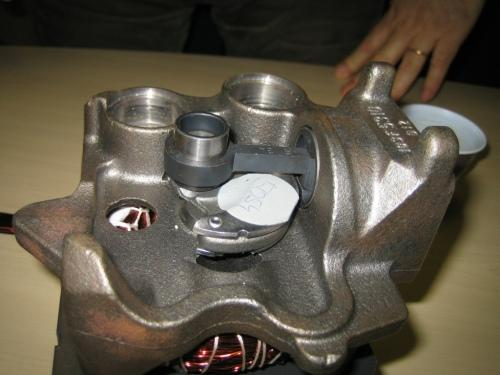 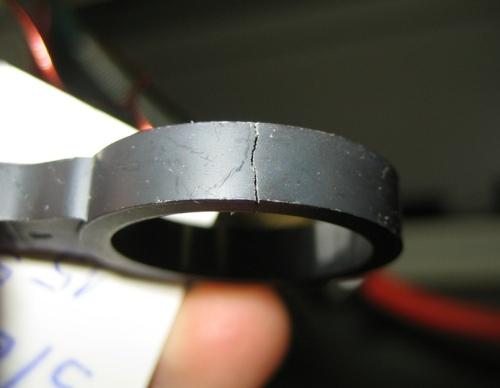

## Load data

close all, clear all, clc, format compact

% industrial data
load nndata.mat
whos

  Name            Size               Bytes  Class     Attributes

  classes         1x3                  342  cell                
  forces       2000x100            1600000  double              
  labels       2000x1                16000  double              



The data were originally acquired on the industrial line of compressors and collected in cooperation with the Laboratory of Synergetics (Faculty of Mechanical Engineering, University of Ljubljana, Slovenia).

The data comprise of 2000 samples of measured forces and corresponding labels, denoting the following classess:

- 'OK'

- 'Overload'

- 'Crack'

In this example, we combine data into two classes only:

- 'OK'

- 'Defect'  (includes 'Overload' and 'Crack')

## Plot data

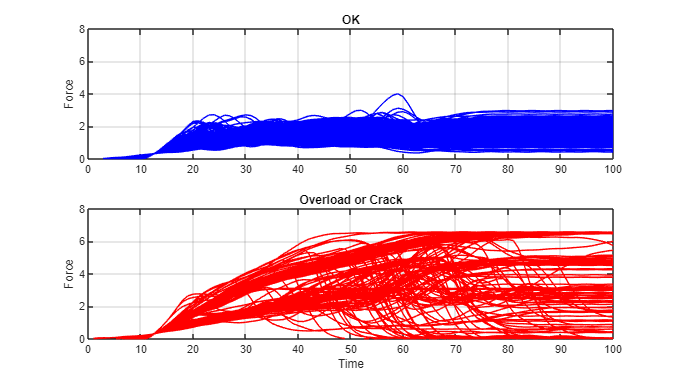

% indexes of OK and NOT_OK samples
iOK  = find(labels==1);
iNOK = find(labels >1);

% figure
figure('Units','Normalized','OuterPosition',[0,0,.4,.4]); % resize figure

% show data for class 1: OK
subplot 211
plot(forces(iOK,:)','b')
grid on
ylim([0 8])
ylabel('Force')
title(classes{1})

% show data for class 2: Overload or Crack
subplot 212
plot(forces(iNOK,:)','r')
grid on
ylim([0 8])
xlabel('Time')
ylabel('Force')
title([classes{2} ' or ' classes{3}])

## Prepare inputs: Data reduction by PCA

First, data need to be standardized (to zero mean and variance one), and then Principal Components Analysis (PCA) is applied for dimensionality reduction. Only the first two principal components are used for subsequent classification. 

The dimensionality reduction by PCA is useful for faster and more stable neural network training, and also for easier visualization of input space and decision boundaries.

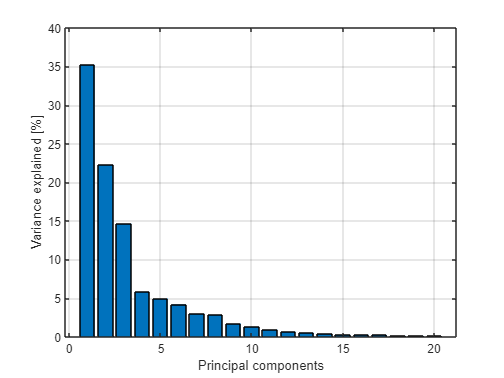

% 1. Standardize inputs to zero mean, variance one
[pn,ps1] = mapstd(forces');

% 2. Apply Principal Compoments Analysis, keep only the first two principal componets
[forces2,score,latent,tsquared,variance_explained] = pca(pn,'NumComponents',2);

% plot the percentage of the total variance explained by the first 20 principal components
figure(2)
bar(variance_explained(1:20))
grid on
xlabel('Principal components')
ylabel('Variance explained [%]')

% display explained variance [%] for each principal component
Variance_Explained = table(variance_explained)

Variance_Explained = 99×1 table
    variance_explained
    __________________
          35.235      
           22.31      
          14.683      
           5.817      
            4.95      
          4.2013      
          3.0337      
          2.8166      
           1.706      
          1.3222      
          0.9502      
         0.64295      
         0.51252      
         0.40501      
         0.25776      
         0.24861      

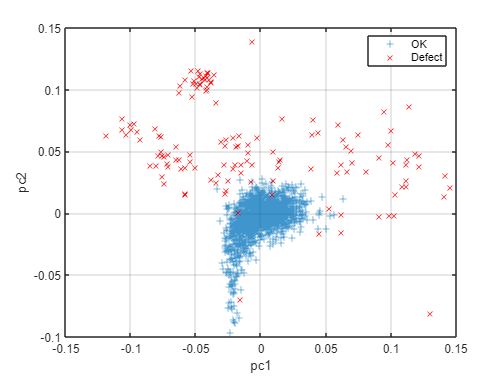

% plot data in the space of the first 2 PCA components
figure(3)
h = plot(forces2(iOK, 1), forces2(iOK, 2),'+'); % OK
grid on, hold on
g = plot(forces2(iNOK,1), forces2(iNOK,2),'rx'); % Faults
xlabel('pc1')
ylabel('pc2')
legend('OK','Defect','location','best')

## Define output coding: 0=OK, 1=Defect

% binary output coding 0/1
labels_defect = double(labels > 1);

## Create and train a multilayer perceptron

Built-in MATLAB function 'feedforwardnet' is used to construct the multilayer perceptron.

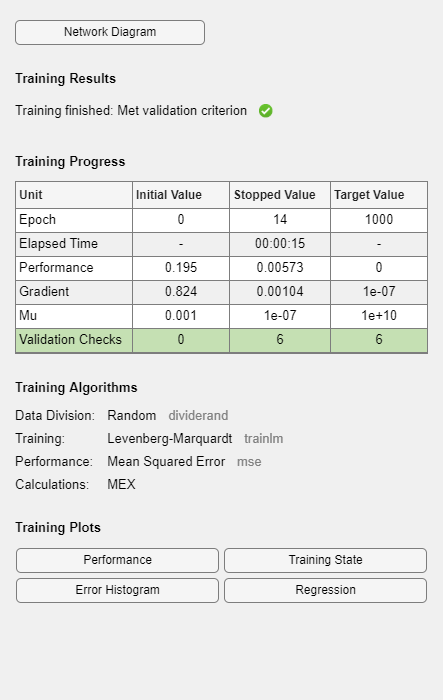

num_hidden_layer =5; % number of neurons in the hidden layer

% create a neural network
net = feedforwardnet([num_hidden_layer]);

% training parameters
net.divideParam.trainRatio = 0.70; % training set [%]
net.divideParam.valRatio   = 0.15; % validation set [%]
net.divideParam.testRatio  = 0.15; % test set [%]

% train a neural network
[net,tr,Y,E] = train(net,forces2',labels_defect');

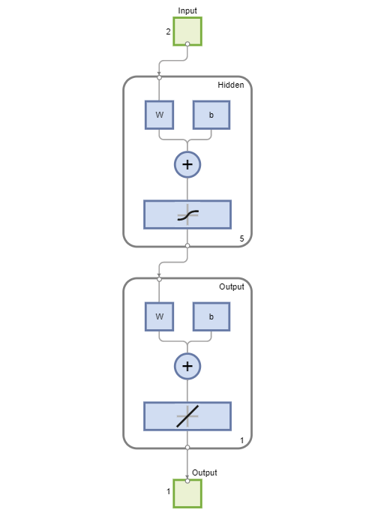

% view net
view(net);

## Evaluate network performance

Evaluate network performance by calculating the classification accuracy. 

% digitize network response
threshold = 0.5;
P = double(Y > threshold)';

% calculate classification accuracy
classification_accuracy = length(find(P==labels_defect))/length(labels_defect)

classification_accuracy = 0.9930

## Plot classification 

The decision boundaries, representing how the trained network classifies the input data, are shown in two colors (representing classes 'OK' and 'Defects').

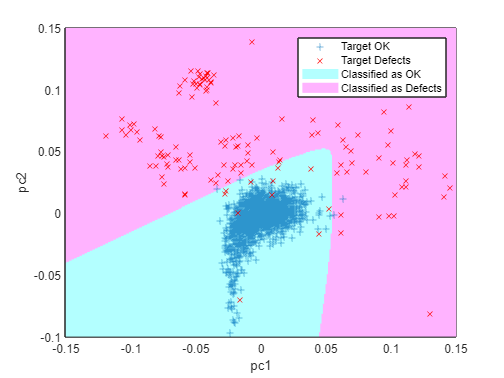

% reuse the last figure
figure(3)
a = axis;

% generate a grid, expand input space
xspan = a(1) : .001 : a(2);
yspan = a(3) : .001 : a(4);
[x1,x2] = meshgrid(xspan,yspan);
xx      = [x1(:) x2(:)]';

% simualte neural network on a grid
y = sim(net,xx);
y = double(y > threshold);

% plot classification regions based on MAX activation
ma = mesh(x1,x2,reshape(-y,length(yspan),length(xspan))-4);
mb = mesh(x1,x2,reshape( y,length(yspan),length(xspan))-5);
set(ma,'facecolor',[.7 1.0 1],'linestyle','none');
set(mb,'facecolor',[1  0.7 1],'linestyle','none');
axis(a)
view(2)
legend([h g ma mb],{'Target OK','Target Defects','Classified as OK','Classified as Defects'},'Location','ne')

% close all windows
close all force

## PowerPoint presentation

[NN4a_Backpropagation.pptx](matlab:open('./NN4a_Backpropagation.pptx'))

[NN8_Practical.pptx](matlab:open('..\NN8 - Practical\NN8_Practical.pptx')) (more information on PCA)